# Predict Behaviour from Ca2+ signal using Machine learning

To see whether the information contained in the dendritic tree is able to predict the current behavioural state of the animal, we can try to use classification or regression between the Ca2+ signal and some behavioural metrics.

## Predictors

The approach requires some predictors, which, in our case are obtained from the GCaMP signal obtained from different part of the dendritic tree. We can use either the entire dendritic tree, or a subset of ROIs from the dendritic tree, or the average between different groups of ROIs (obtained, for example from a previous clustering analysis)

## Predictors preprocessing

Predictors correspond to Ca2+ signal. However, a number of preprocessing steps can be used:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use obj.rescaled_traces (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Observations

If we want to predict the behaviour from the Ca2+, we can use obj.behaviours. Classifiers require a binnarization step, while regression do not

# 1. Load experiment

Here we will directly use the existing arboreal_scan_object. For more advanced use cases, see Demo_FINAL_SERIES_OF_ANALYSIS

% folder_to_use = 'C:\Users\Antoine.Valera\MATLAB\newextraction_raw_zscored - All - Backup\2019-10-01_exp_1';
% obj = arboreal_scan_experiment(folder_to_use);

obj; % This is a current arboreal_scan_object in your base workspace

Unrecognized function or variable 'obj'.

# 2. Define the Analysis Settings

## Arboreal Scan settings

	INFO : obj.binned_data.median traces were computed using rescaled signals


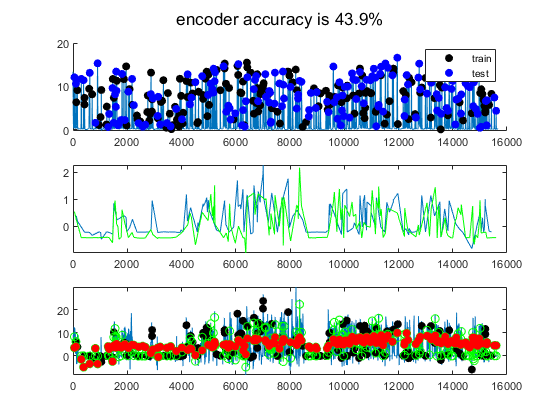

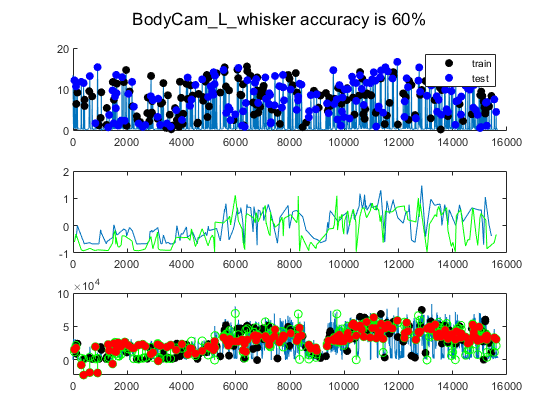

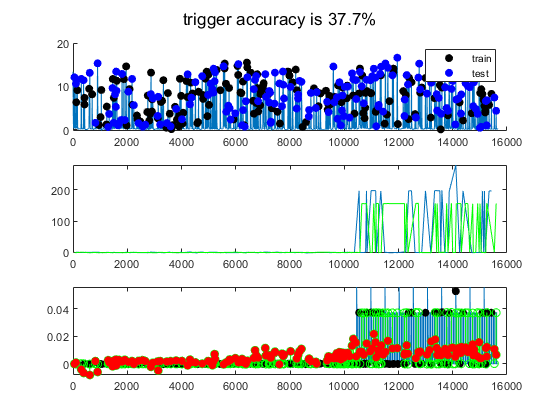

p = 1; Conditions do not significantly differ from each other


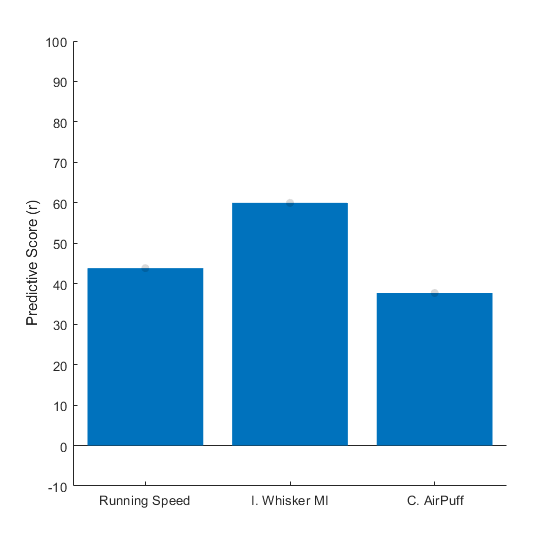

%% The following settings will affect the events detected, the rescaling process, the event amplitude and median subtracted amplitude, as well as the excluded ROIs. Make sure this is all correct for you
obj.detrend                         = 0;            
obj.rendering                       = 0;
obj.time_smoothing                  = [-1.5, 0];
obj.thr_for_detection               = 0.2;
obj.bad_ROI_thr                     = 0.7;

## Behaviour Settings

%% We'll have 3 behaviours available. For more, see obj.behaviours.types. There are many more advaced behaviour options. See Demo_FINAL_SERIES_OF_ANALYSIS for a more tighly-defined set of behaviours
behaviours                          = {'encoder','BodyCam_L_whisker','trigger'};
obj.beh_smoothing                   = [-1.5, 0];

## Initialize metrics / regenerate them

	INFO : obj.binned_data.median traces were computed using rescaled signals
p = 1; Conditions do not significantly differ from each other


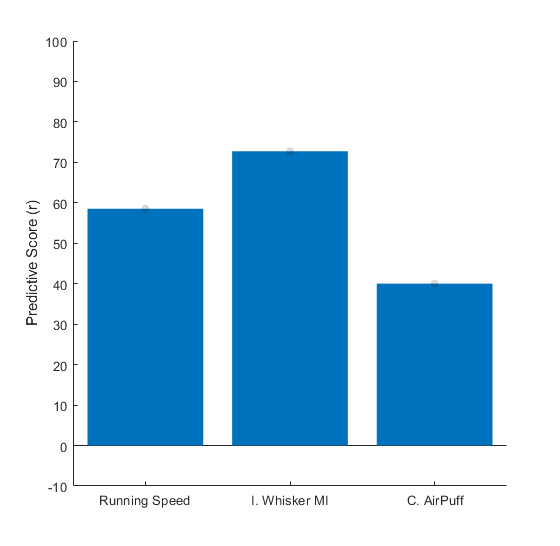

obj.process({'distance',50});       % will use obj.time_smoothing and obj.rendering

## Machine Learning settings

	INFO : obj.binned_data.median traces were computed using rescaled signals
some conditions are significantly different from others


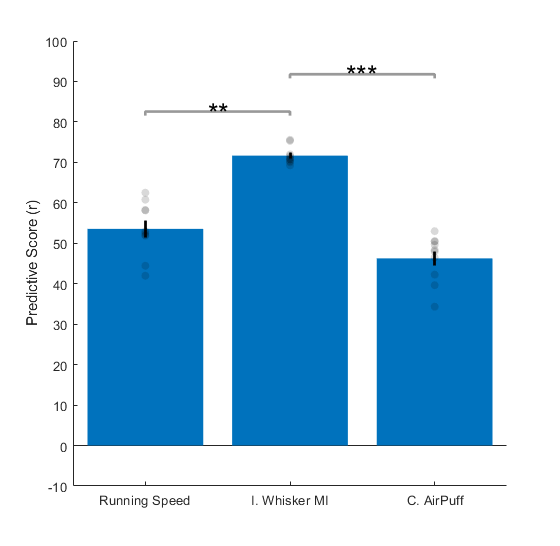

ml_parameters = machine_learning_params(); % We'll start with the default options everywhere, and upate them on demand

# 3. Run a simple linear regression model

## 3.1.1 Run a simple linear regression model once, on all 3 behaviours, with all ROIs using the peaks amplitude

results             = predict_behaviours(obj,'peaks'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

	INFO : obj.binned_data.median traces were computed using rescaled signals
some conditions are significantly different from others


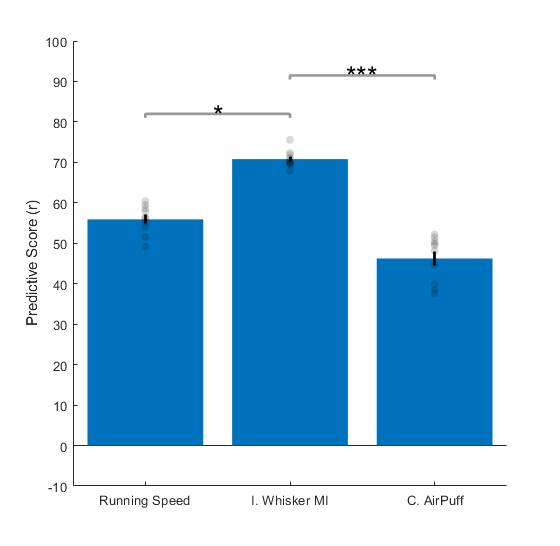

%% From now on, we'll only plot the final result
ml_parameters.rendering = 1;

## 3.1.2 Run a simple linear regression model once, on all 3 behaviours, with all ROIs using the peaks modulation

results             = predict_behaviours(obj,'peaks_subtracted' ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

## 3.2 Same as above, running the model 10 times

%% Increasing the number of repetition will enable statistical testing
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'N_iter',10);     % see defaults at the top); 

	INFO : obj.binned_data.median traces were computed using rescaled signals



%% From now on, we'll do 10 iteration every time
ml_parameters.N_iter = 10;

## 3.3.1 Same as above, but doing hyperparameter optimization, using the native matlab method

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1 %
Iteration : 2 %
Iteration : 3 %
Iteration : 4 %
Iteration : 5 %
Iteration : 6 %
Iteration : 7 %
Iteration : 8 %
Iteration : 9 %
Iteration : 10 %
some conditions are significantly different from others


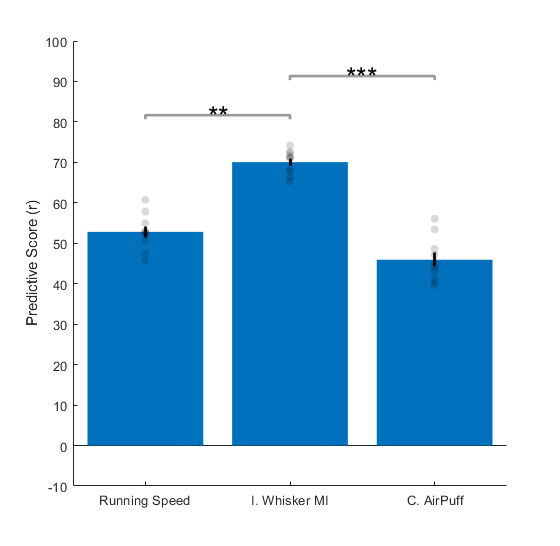

%% Hyperparameter optimization will improve the performances for each iteration of the model
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'optimize_hyper', true);     % see defaults at the top);  


%% From now on, we'll always do hyperparemters optimization
ml_parameters.optimize_hyper = true;


## 3.3.1 Same as above, but doing hyperparameter optimization, using the native matlab method

%% Manual Hyperparameter optimization is faster than the native method
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1


                                             'optimization_method', 'manual');     % see defaults at the top);  

%% From now on, we'll always do hyperparemters optimization
ml_parameters.optimization_method = 'manual';

# 4. Run a simple svm regression model

## 4.1 Run a svm regression model 10 times, on all 3 behaviours, with all ROIs using the peaks modulation

%% Increasing the number of repetition will enable statistical testing
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'method', 'svm');    % svm model. This has its own hyperparameter optimization routine

# 5. Run a classifier

## 5.1 Example : SVM classifier on all behaviours

% This is the default case : svm classifier
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'method', 'svm', 'use_classifier', 'true');     % see defaults at the top);  